Uppgift 1

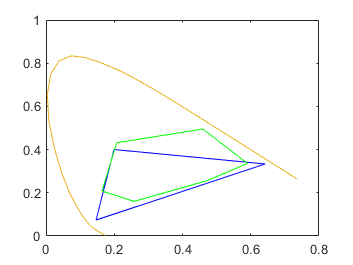

dell = load("Dell.mat").XYZdell;
inkjet = load("Inkjet.mat").XYZinkjet;

plot_chrom(dell,"blue");
hold on
plot_chrom(inkjet,"green");
hold off

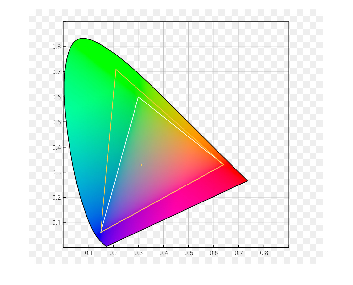


colorspace = imread("ColorSpace.jpg");
imshow(colorspace); % Just to show color space, blue triangle is dell & green is inkjet

Uppgift 2.1

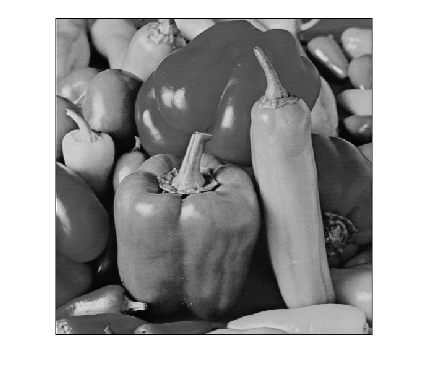

peppers_gray = imread("peppers_gray.tif");
peppers_gray = im2double(peppers_gray);

snr = mysnr(peppers_gray,1); % test bara


%2.1.1
imshow(peppers_gray);


nearest = imresize(imresize(peppers_gray,0.25,'nearest'),4,'nearest');
disp("nearest: " + mysnr(peppers_gray,peppers_gray -nearest));

nearest: 17.0956


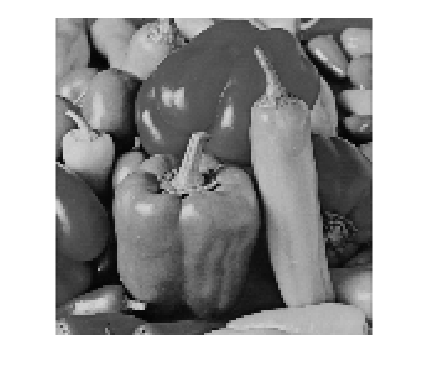

imshow(nearest);


bilinear = imresize(imresize(peppers_gray,0.25,'bilinear'),4,'bilinear');
disp("bilinear: " + mysnr(peppers_gray,peppers_gray - bilinear));

bilinear: 18.8922


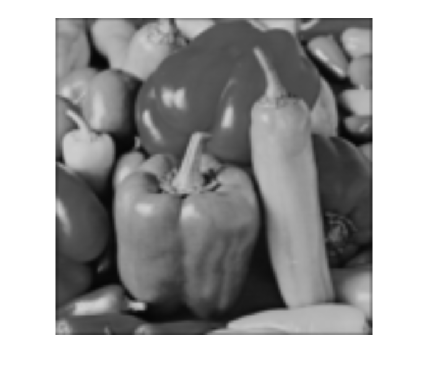

imshow(bilinear);


bicubic = imresize(imresize(peppers_gray,0.25,'bicubic'),4,'bicubic');
disp("bicubic: " + mysnr(peppers_gray,peppers_gray -bicubic));

bicubic: 19.8538


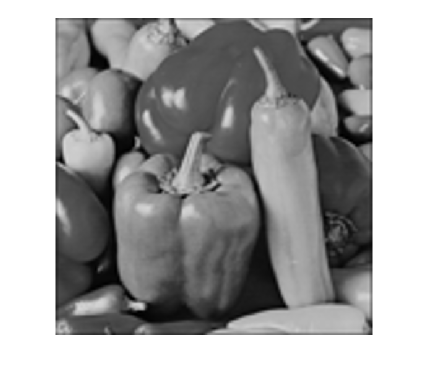

imshow(bicubic);


% Not exactly, while the SNR of nearest is the best, i think that the best
% looking one is from bicubic, bilinear looks more blurry.


% 2.1.2
thresh = peppers_gray>=0.5;
thresh = im2double(thresh);
halftone = dither(peppers_gray);
halftone = im2double(halftone);
disp("halftone: " + mysnr(peppers_gray, halftone-peppers_gray));

halftone: 0.41121


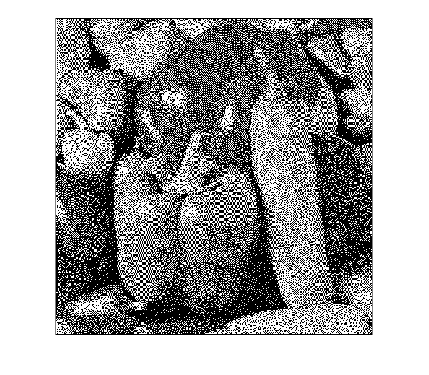

imshow(halftone);

disp("thresh: " + mysnr(peppers_gray,peppers_gray -thresh));

thresh: 2.9721


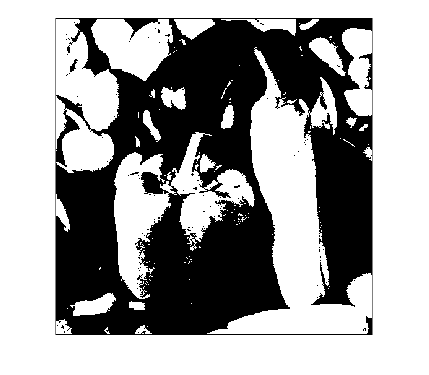

imshow(thresh);


% haftone is better. Dots makes it looks like it is not only blck and white
% for our brain.



Uppgift 2.2

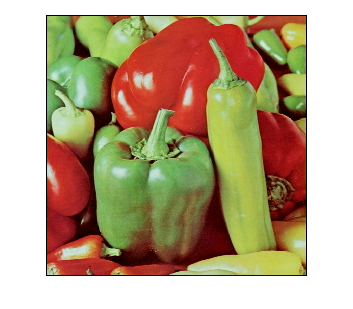

peppers_RGB = imread("peppers_color.tif");
peppers_RGB = im2double(peppers_RGB);
imshow(peppers_RGB);

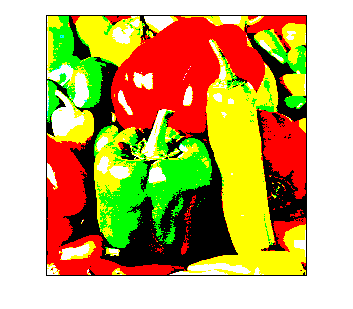


thresh = peppers_RGB>= 0.5;
thresh = im2double(thresh);
% imshow(thresh) % blir exakt likadan som om man gör som rad 59-66

halftone1 = thresh(:,:,1);
halftone2 = thresh(:,:,2);
halftone3 = thresh(:,:,3);
halftoneR = double(halftone1);
halftoneG = double(halftone2);
halftoneB = double(halftone3);
thresh_RGB = cat(3,halftoneR,halftoneG,halftoneB);
imshow(thresh_RGB);

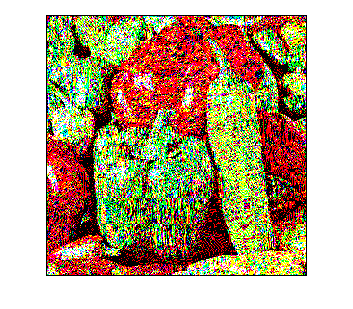


halftone1 = dither(peppers_RGB(:,:,1));
halftone2 = dither(peppers_RGB(:,:,2));
halftone3 = dither(peppers_RGB(:,:,3));
halftone1 = double(halftone1);
halftone2 = double(halftone2);
halftone3 = double(halftone3);
dither_RGB = cat(3,halftone1,halftone2,halftone3);
imshow(dither_RGB);


original_lab = rgb2lab(peppers_RGB);
thresh_lab = rgb2lab(thresh_RGB);
dither_lab = rgb2lab(dither_RGB);

diff_thresh = sqrt((original_lab(:,:,1) - thresh_lab(:,:,1)).^2 + (original_lab(:,:,2) - thresh_lab(:,:,2)).^2 + (original_lab(:,:,3) - thresh_lab(:,:,3)).^2);
diff_dither = sqrt((original_lab(:,:,1) - dither_lab(:,:,1)).^2 + (original_lab(:,:,2) - dither_lab(:,:,2)).^2 + (original_lab(:,:,3) - dither_lab(:,:,3)).^2);
disp("diff_thresh: " + 1/(512*512)*sum(diff_thresh,"all"));

diff_thresh: 50.1577


disp("diff_dither: " + 1/(512*512)*sum(diff_dither,"all"));

diff_dither: 72.8423



% dither ser bättre ut. Men thresh har lägre diff



Uppgift 3

clear
peppers_gray = imread("peppers_gray.tif");
peppers_gray = im2double(peppers_gray);

thresh = peppers_gray>=0.5;
thresh = double(thresh);
halftone = dither(peppers_gray);
halftone = double(halftone);

disp("halftone: " + snr_filter(peppers_gray,halftone - peppers_gray));

halftone: 13.323


imshow(halftone);

disp("thresh: " + snr_filter(peppers_gray,thresh - peppers_gray));

thresh: 3.3488


imshow(thresh);


% Apply this metric to the two halftones in assignment 2.1.2. Does the result correlate better 
%with your judgment of quality
% halftone is extremly simular, hardly see any differens but the second has
% 13 snr value and the first has 0.4 so in theory the second should be
% better bc higher snr gives a sharper result.


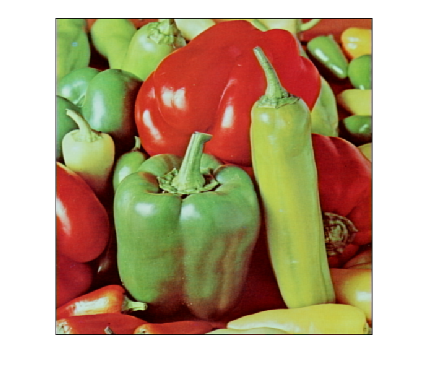


peppers_RGB = imread("peppers_color.tif");
peppers_RGB = im2double(peppers_RGB);

f=MFTsp(15,0.0847,500);
R = peppers_RGB(:,:,1);
G = peppers_RGB(:,:,2);
B = peppers_RGB(:,:,3);
R=conv2(peppers_RGB(:,:,1),f,'same');
G=conv2(peppers_RGB(:,:,2),f,'same');
B=conv2(peppers_RGB(:,:,3),f,'same');
R = (R>0).*R;
G = (G>0).*G;
B = (B>0).*B;

filter_RGB = cat(3,R,G,B);
imshow(filter_RGB);


thresh = peppers_RGB>= 0.5;
thresh = im2double(thresh);
halftone1 = thresh(:,:,1);
halftone2 = thresh(:,:,2);
halftone3 = thresh(:,:,3);
halftone1 = im2double(halftone1);
halftone2 = im2double(halftone2);
halftone3 = im2double(halftone3);
halftone1 =conv2(halftone1,f,'same');
halftone2 =conv2(halftone2,f,'same');
halftone3 =conv2(halftone3,f,'same');
thresh_RGB = cat(3,halftone1,halftone2,halftone3);

halftone1 = dither(peppers_RGB(:,:,1));
halftone2 = dither(peppers_RGB(:,:,2));
halftone3 = dither(peppers_RGB(:,:,3));
halftone1 = im2double(halftone1);
halftone2 = im2double(halftone2);
halftone3 = im2double(halftone3);
halftone1 =conv2(halftone1,f,'same');
halftone2 =conv2(halftone2,f,'same');
halftone3 =conv2(halftone3,f,'same');
dither_RGB = cat(3,halftone1,halftone2,halftone3);


original_lab = rgb2lab(filter_RGB);
thresh_lab = rgb2lab(thresh_RGB);
dither_lab = rgb2lab(dither_RGB);

diff_thresh = sqrt((original_lab(:,:,1) - thresh_lab(:,:,1)).^2 + (original_lab(:,:,2) - thresh_lab(:,:,2)).^2 + (original_lab(:,:,3) - thresh_lab(:,:,3)).^2);
diff_dither = sqrt((original_lab(:,:,1) - dither_lab(:,:,1)).^2 + (original_lab(:,:,2) - dither_lab(:,:,2)).^2 + (original_lab(:,:,3) - dither_lab(:,:,3)).^2);
1/(512*512)*sum(diff_thresh,"all")

ans = 48.1582

1/(512*512)*sum(diff_dither,"all")

ans = 20.2107

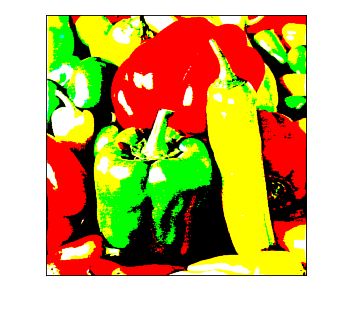


imshow(thresh_RGB);

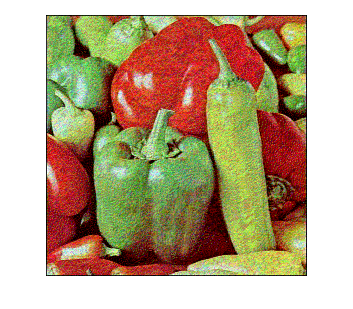

imshow(dither_RGB);

% Now the dithered picture gets better result by long shot and matches
% better with visual judgement




Uppgift 4.1

peppers_RGB = imread("peppers_color.tif");
peppers_RGB = im2double(peppers_RGB);
peppers_xyz = rgb2xyz(peppers_RGB);
ppi = 112; d = 10; % för 27 tum 1440p skärm, 0.25m (10tum) bort
sampPerDegree = ppi*d*tan(pi/180);
result = mean(scielab(sampPerDegree,peppers_RGB,peppers_xyz,[95.05, 100, 108.9],'xyz'),"all");

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("original: " + result);

original: 8.4692


imshow(peppers_RGB);


nearest = imresize(imresize(peppers_RGB,0.25,'nearest'),4,'nearest');
nearest_xyz = rgb2xyz(nearest);
result = mean(scielab(sampPerDegree,nearest_xyz,peppers_xyz,[95.05, 100, 108.9],'xyz'),"all");

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("nearest: " + result);

nearest: 0.26313


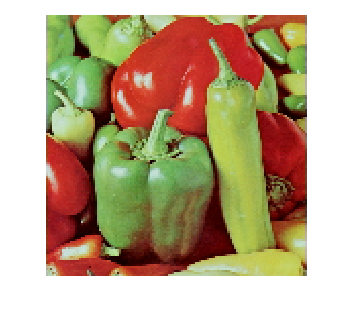

imshow(nearest);


bilinear = imresize(imresize(peppers_RGB,0.25,'bilinear'),4,'bilinear');
bilinear_xyz = rgb2xyz(bilinear);
result = mean(scielab(sampPerDegree,bilinear_xyz,peppers_xyz,[95.05, 100, 108.9],'xyz'),"all");

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("bilinear: " + result);

bilinear: 0.2643


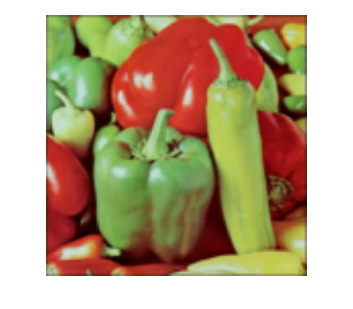

imshow(bilinear);


bicubic = imresize(imresize(peppers_RGB,0.25,'bicubic'),4,'bicubic');
bicubic_xyz = rgb2xyz(bicubic);
result = mean(scielab(sampPerDegree,bicubic_xyz,peppers_xyz,[95.05, 100, 108.9],'xyz'),"all");

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("bicubic: " + result);

bicubic: 0.19329


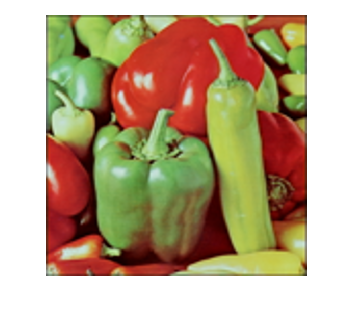

imshow(bicubic);


% not really, they have very close s-cielab values (within 0.2) of each
% other but they look very different on the screen to me



Uppgift 4.2

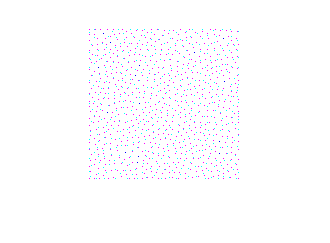

col = load("colorhalftones.mat");
c1 = col.c1; c2 = col.c2; c3 = col.c3; c4 = col.c4; c5 = col.c5;
ppi = 112; d = 10; % for 27 inch 1440p disp from 0.25m away
sampPerDegree = ppi*d*tan(pi/180);

imshow(c1);

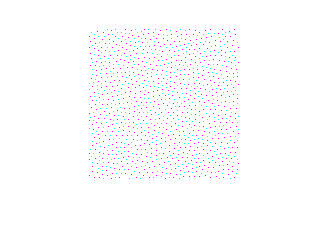

imshow(c2);


c1_xyz = rgb2xyz(c1);
result1 = scielab(sampPerDegree,c1_xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


std_dev_c1 = std2(result1(:,:,1)) + std2(result1(:,:,2)) + std2(result1(:,:,3));
disp("c1 std_dev: " + std_dev_c1);

c1 std_dev: 0.073116


c2_xyz = rgb2xyz(c2);
result2 = scielab(sampPerDegree,c2_xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


std_dev_c2 = std2(result2(:,:,1)) + std2(result2(:,:,2)) + std2(result2(:,:,3));
disp("c2 std_dev: " + std_dev_c2);

c2 std_dev: 0.069921


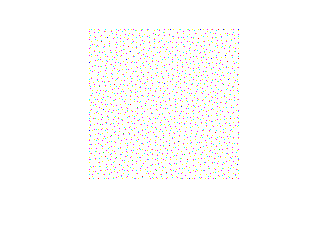

% c2 seems more irregular, but both seem pretty similar in granularity, it
% is reflekted in the std_dev because both seem to have about same. smaller
% value -> more irregular

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

imshow(c3);

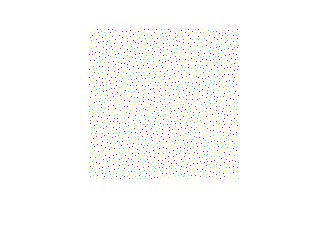

imshow(c4);

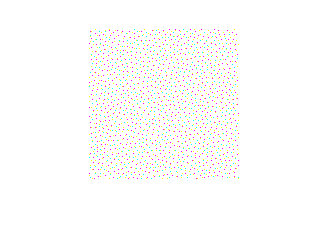

imshow(c5);


c3_xyz = rgb2xyz(c3);
result = scielab(sampPerDegree,c3_xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


disp("c3 std_dev: " + std2(result));

c3 std_dev: 0.41022


c4_xyz = rgb2xyz(c4);
result = scielab(sampPerDegree,c4_xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


disp("c4 std_dev: " + std2(result));

c4 std_dev: 0.41015


c5_xyz = rgb2xyz(c5);
result = scielab(sampPerDegree,c5_xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


disp("c5 std_dev: " + std2(result));

c5 std_dev: 0.41009


% again, they all have very similar results



Uppgift 5

peppers_gray = imread("peppers_gray.tif");
peppers_gray = im2double(peppers_gray);
%%%%%%%%%%%%%%%%%% a)

dist1 = peppers_gray;
size = 512;
for n = 1:1:size
    if mod(n,2) ~= 0
        dist1(n,:) = dist1(n,:) + 0.1;
    else
        dist1(n,:) = dist1(n,:) - 0.1;
    end
end

dist2 = peppers_gray;
for n = 1:1:256
    for m = 1:1:512
        dist2(n,m) = dist2(n,m) + 0.1;
    end
end
for n = 257:1:512
    for m = 1:1:512
        dist2(n,m) = dist2(n,m) - 0.1;
    end
end
% same snr becuase we still got the same median value in the image.

[ssim1,map1] = ssim(dist1,peppers_gray);
[ssim2,map2] = ssim(dist2, peppers_gray);
ssim1

ssim1 = 0.2435

snr1 = mysnr(peppers_gray,dist1 - peppers_gray)

snr1 = 13.4303

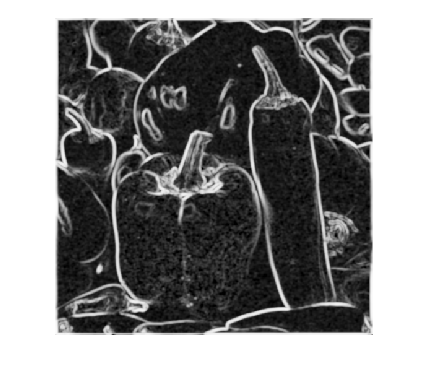

imshow(map1);

ssim2

ssim2 = 0.8528

snr2 = mysnr(peppers_gray,dist2 - peppers_gray)

snr2 = 13.4303

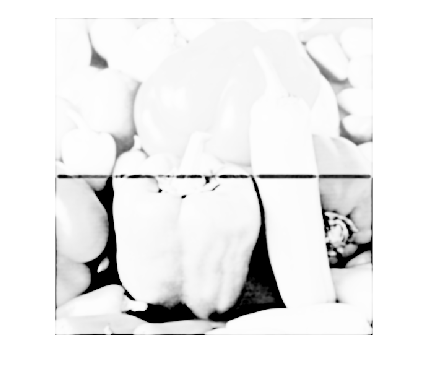

imshow(map2);

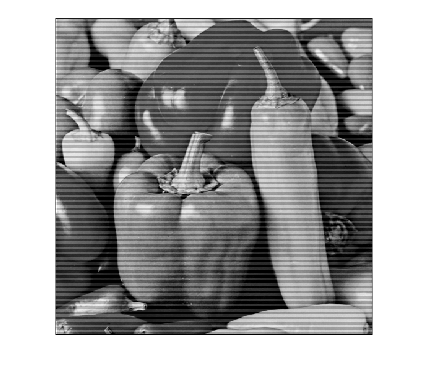

imshow(dist1)

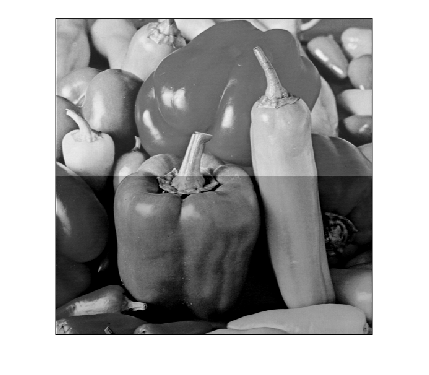

imshow(dist2)

% the second distorition is the change done in a big step compare the second
% that have a more steps. So the first is better beacuse the changes does
% not disturb as much.

%%%%%%%%%%%%%%%%%% b)
dist1 = peppers_gray+0.2*(rand(512)-0.5);
f = fspecial('gaussian',21,10);
dist2 = filter2(f,peppers_gray);

[ssim1,map1] = ssim(dist1,peppers_gray);
ssim1

ssim1 = 0.4336

snr1 = mysnr(peppers_gray,dist1 - peppers_gray)

snr1 = 18.1991

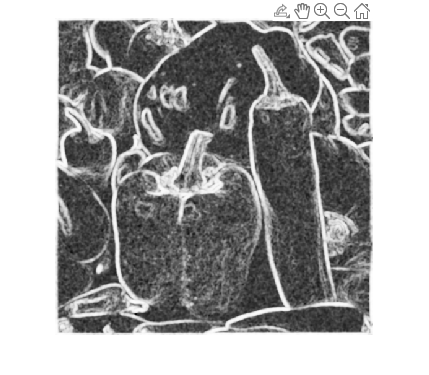

imshow(map1);


[ssim2,map2] = ssim(dist2,peppers_gray);
ssim2

ssim2 = 0.6773

snr2 = mysnr(peppers_gray,dist2 - peppers_gray)

snr2 = 14.9577

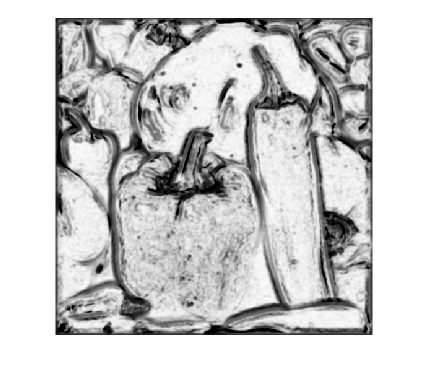

imshow(map2);

% according to snr the first distortion is better than the second one,
% because the values of the pixels arent changed much for the first
% distortion compared to the second
% according to ssim the second is better compared to the first one because
% the second one has a better comformity accros the whole image compared to
% the first one, not as grating with less noise and less change accross
% image